clear all;
close all;
%start time is July 10 2020 17:00:00
startTime = 20200710170000;
%end time is July 16 2020 00:00:00
endTime = 20200716000000;
%stn 045
stnID = 045;
gliderTable = readtable('metbuoy_19-04.csv');

cdipid = stnID; 
%convert startTime for cdip
    startTimestr = int2str(startTime);
    y_start = str2num(startTimestr(:,1:4));
    m_start = str2num(startTimestr(:,5:6));
    d_start = str2num(startTimestr(:,7:8));
    h_start = str2num(startTimestr(:,9:10));
    min_start = str2num(startTimestr(:,11:12));
    s_start = str2num(startTimestr(:,13:14));
    %convert endTime
    endTimestr = int2str(endTime);
    y_end = str2num(endTimestr(:,1:4));
    m_end = str2num(endTimestr(:,5:6));
    d_end = str2num(endTimestr(:,7:8));
    h_end = str2num(endTimestr(:,9:10));
    min_end = str2num(endTimestr(:,11:12));
    s_end = str2num(endTimestr(:,13:14));

tlims = [datenum(y_start,m_start,d_start,h_start,min_start,s_start) datenum(y_end, m_end,d_end,h_end,min_end,s_end)]; 

% spectral data etc. ------------------------------------------------------
clear cdip;
tres = 1;

varnm = 'Time';
[cdip.time] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Hs';
[cdip.hs] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Tp';
[cdip.tp] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'EnergyDensity';
[cdip.sf, cdip.f] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'MeanDirection';
[cdip.md] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



%get waveglider time and wind vectors for appropriate times
[wgt,wgWind,wgMeanDir,~] = gliderTime(gliderTable, startTime, endTime);

%remove waveglider times that have no corresonding values in energy times
t_wind_new = NaN(length(cdip.time),1);
wind_wave_indices = NaN(length(cdip.time),1);
diff = 1000;
index = 1;
    for i = 1:length(cdip.time)
      for j = 1:length(wgt)
        if abs(cdip.time(i)-wgt(j)) < diff
            diff = abs(cdip.time(i)-wgt(j));
            index = j;
        end
      end
      t_wind_new(i) = wgt(index);
      wind_wave_indices(i) = index;
      index = 1;
      diff = 1000;
    end    
%new wind speeds
wgWind = wgWind(wind_wave_indices);
%new mean direction
wgMeanDir = wgMeanDir(wind_wave_indices);
%new wind times
wgt = wgt(wind_wave_indices);

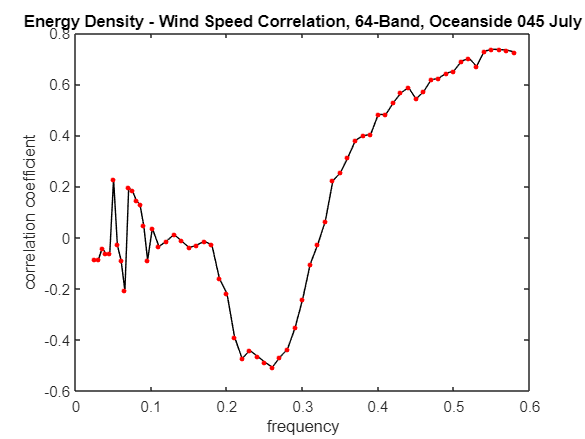

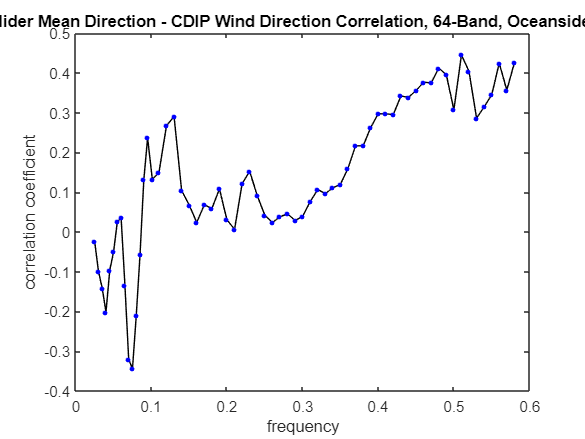

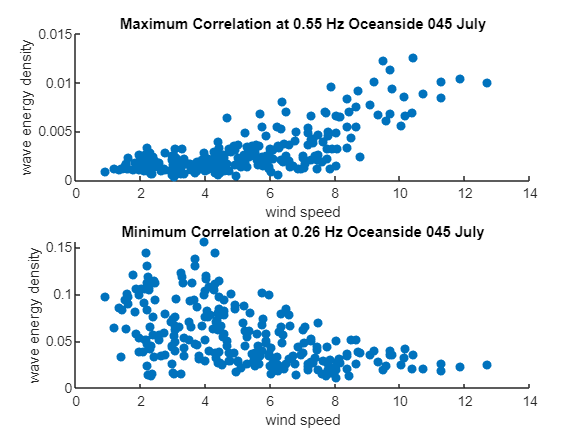

corr =    -0.0855   -0.0860   -0.0416   -0.0628   -0.0617    0.2289   -0.0279   -0.0901   -0.2080    0.1957    0.1830    0.1455    0.1282    0.0453   -0.0883    0.0360   -0.0351   -0.0135    0.0120   -0.0133   -0.0396   -0.0292   -0.0140   -0.0289   -0.1602   -0.2197   -0.3890   -0.4736   -0.4410   -0.4637   -0.4870   -0.5072   -0.4673   -0.4363   -0.3529   -0.2415   -0.1046   -0.0269    0.0641    0.2222    0.2540    0.3140    0.3810    0.3981    0.4036    0.4816    0.4811    0.5278    0.5657    0.5871


dircorr =    -0.0241   -0.0984   -0.1417   -0.2016   -0.0960   -0.0504    0.0256    0.0351   -0.1336   -0.3202   -0.3445   -0.2108   -0.0571    0.1310    0.2362    0.1322    0.1490    0.2671    0.2901    0.1041    0.0674    0.0238    0.0681    0.0586    0.1080    0.0302    0.0064    0.1213    0.1524    0.0911    0.0420    0.0236    0.0379    0.0452    0.0289    0.0389    0.0760    0.1064    0.0962    0.1111    0.1197    0.1598    0.2165    0.2161    0.2623    0.2972    0.2965    0.2954    0.3417    0.3384


[corr, dircorr] = windWaveCorr64(' Oceanside 045 July', wgWind, wgMeanDir, cdip)

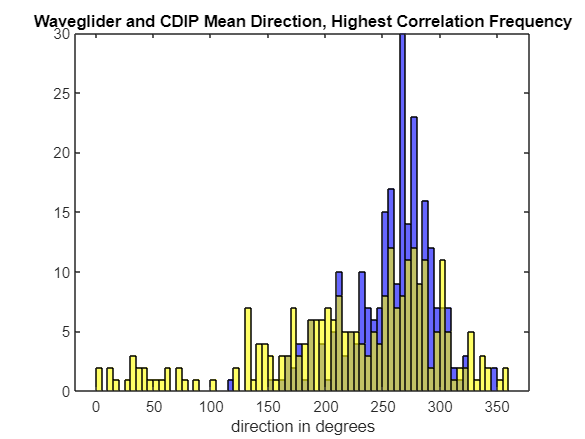

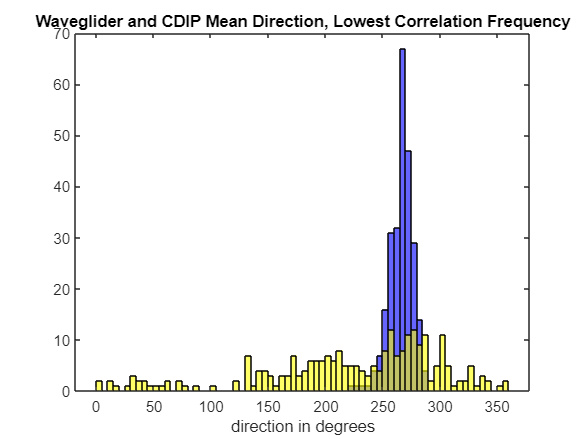

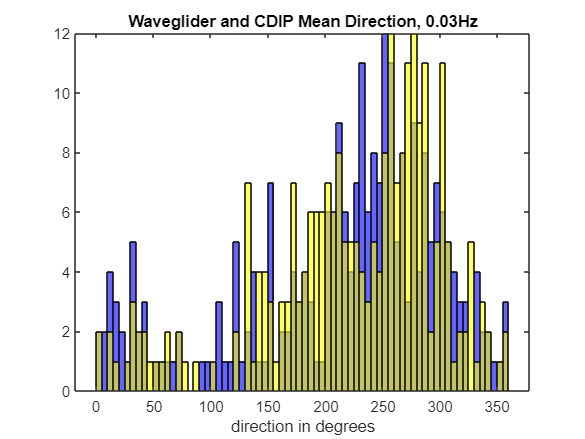

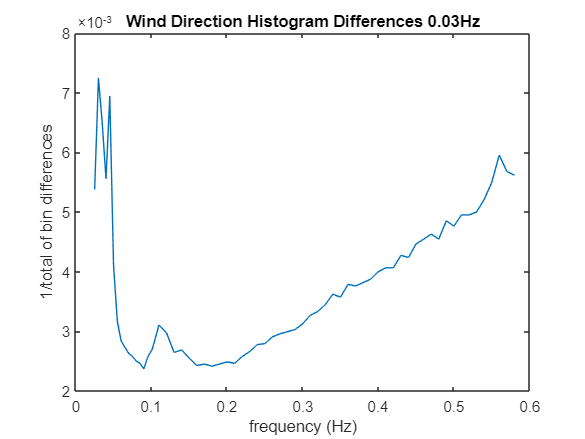

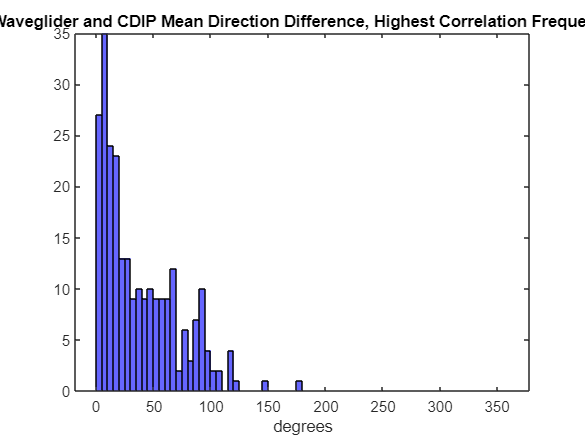

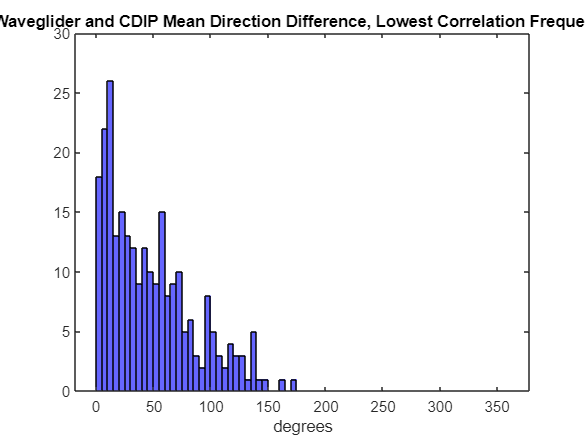

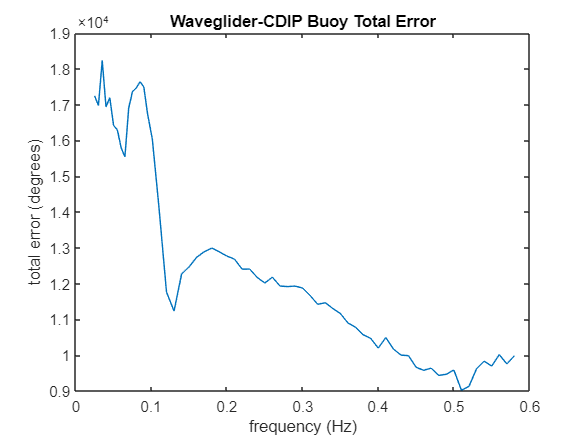

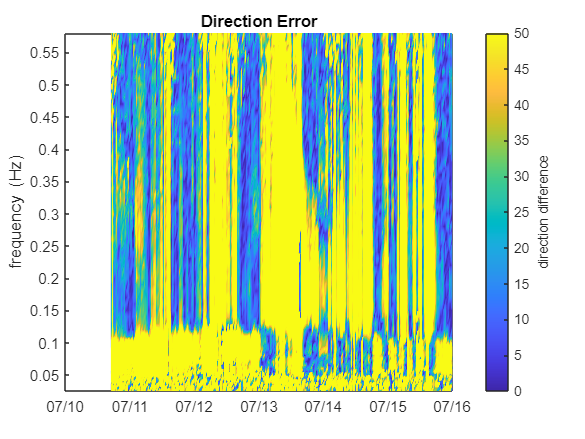

hist =     0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1013    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400
    0.0054    0.0072    0.0065    0.0056    0.0069    0.0041    0.0032    0.0028    0.0027    0.0026    0.0026    0.0025    0.0025    0.0024    0.0026    0.0027    0.0031    0.0030    0.0026    0.0027    0.0026    0.0024    0.0025    0.0024    0.0025    0.0025    0.0025    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030    0.0030    0.0031    0.0033    0.0033    0.0034    0.0036    0.0036    0.0038    0.0038    0.0038    0.0039    0.0040    0.0041    0.0041    0.0043  

%direction histograms
hist = dir_histogram(cdip, wgMeanDir, corr)

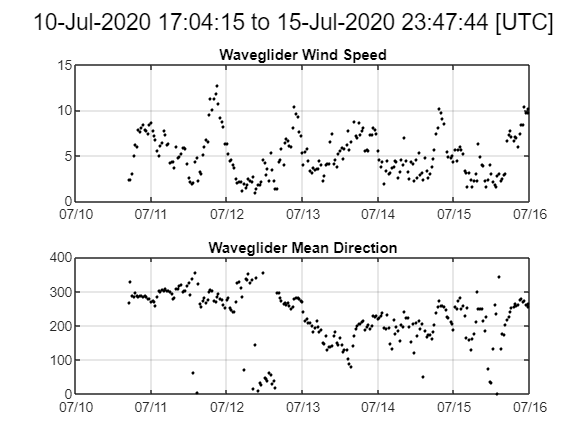

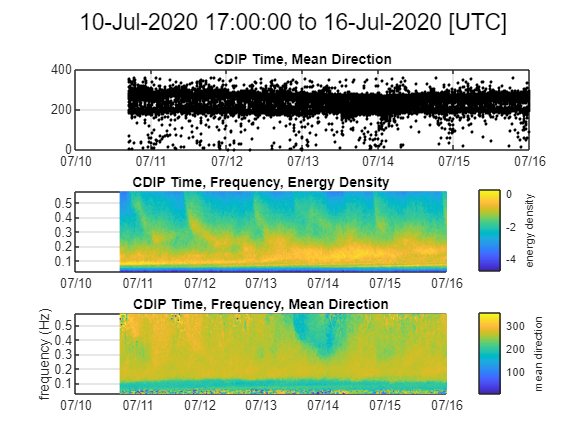

%pcolor plot
pcolor_plot(wgt, wgWind, wgMeanDir, cdip)

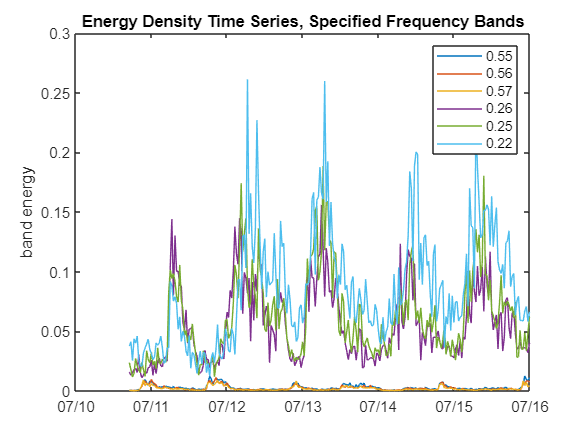

%energy density time series for selected frequency bands
freqplot(cdip, corr)